clear

Part a

a = 1;      % Amplitude
f = 2;      % Frequency
w = 2*pi*f; % Angular Frequency
phi = pi/3; % Phase Angle

v1 = @(t) a/2 * exp(1i*(w*t+phi));
v2 = @(t) a/2 * exp(-1i*(w*t+phi));
y = @(t) v1(t) + v2(t);

Part b

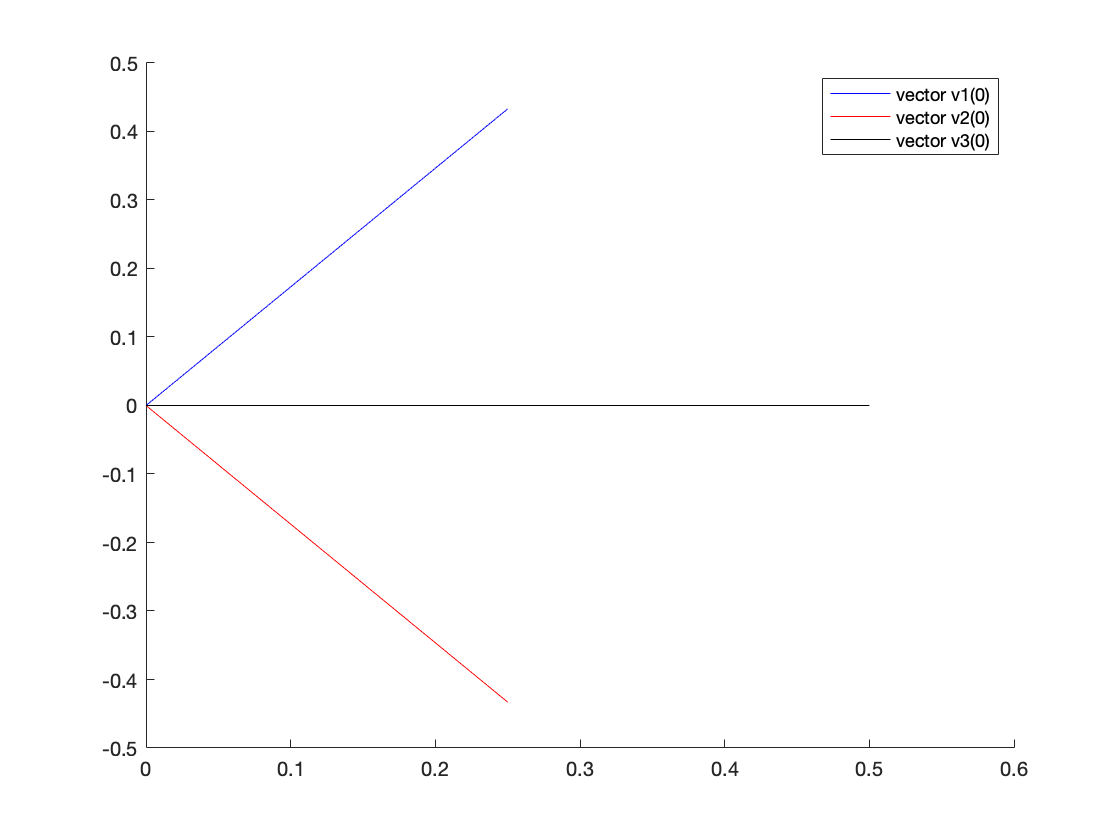

hold on
plot([0 real(v1(0))], [0 imag(v1(0))], 'b')
plot([0 real(v2(0))], [0 imag(v2(0))], 'r')
plot([0 real(y(0))], [0 imag(y(0))], 'k')
legend("vector v1(0)", "vector v2(0)", "vector v3(0)")
hold off

Part c

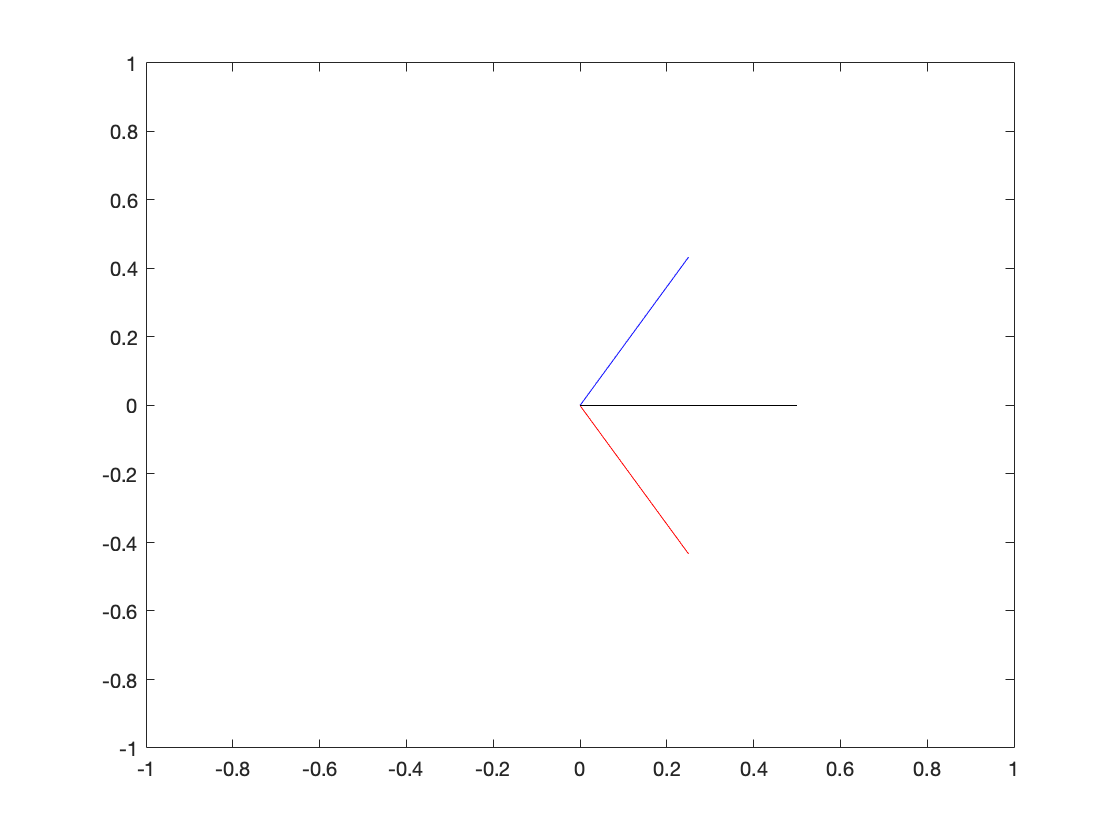

figure()
for t = 0:0.01:2
    plot([0 real(v1(t))], [0 imag(v1(t))], 'b')
    hold on
    axis([-1 1 -1 1])
    plot([0 real(v2(t))], [0 imag(v2(t))], 'r')
    plot([0 real(y(t))], [0 imag(y(t))], 'k')
    pause(0.2)
    hold off
end

Part d

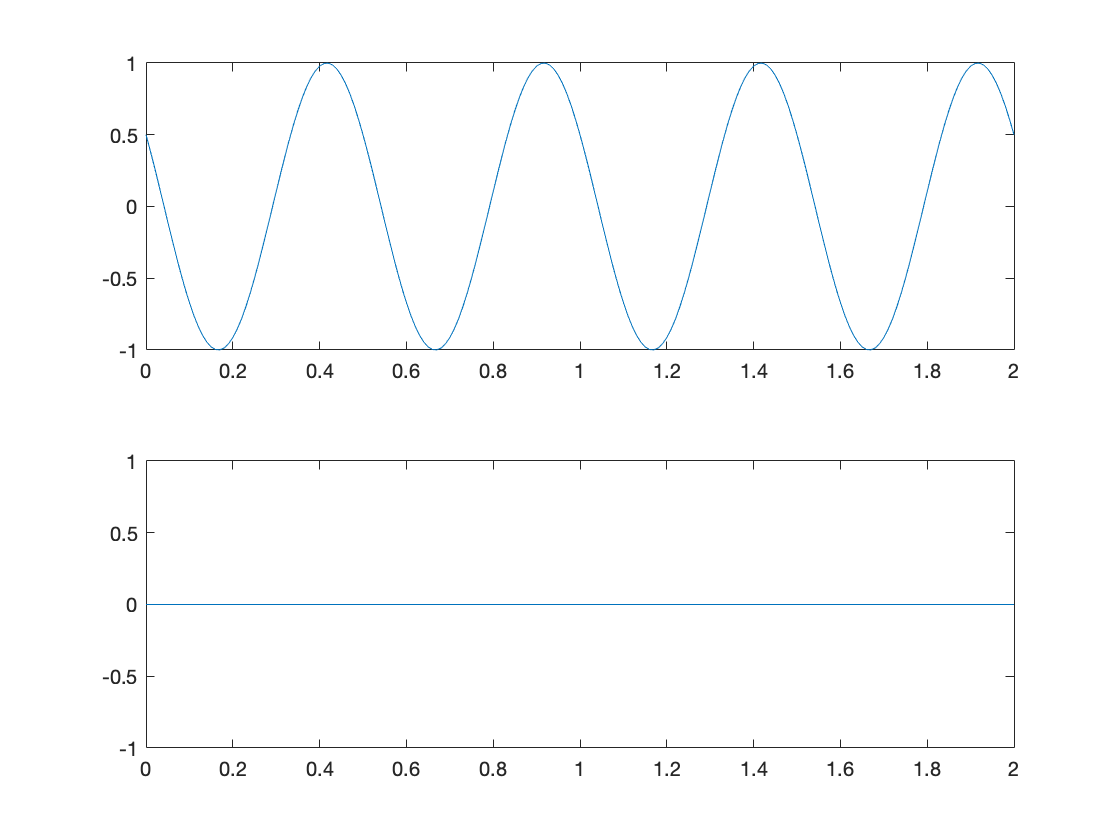

figure();
t = 0:0.01:2;
subplot(2,1,1)
plot(t, real(y(t)))
subplot(2,1,2)
plot(t, imag(y(t)))